clc; clear all; close all;


**Calcul de l'angle de rotation du robot en fonction de l'inertie de la flywheel (pour une vitesse angulaire donnée)**

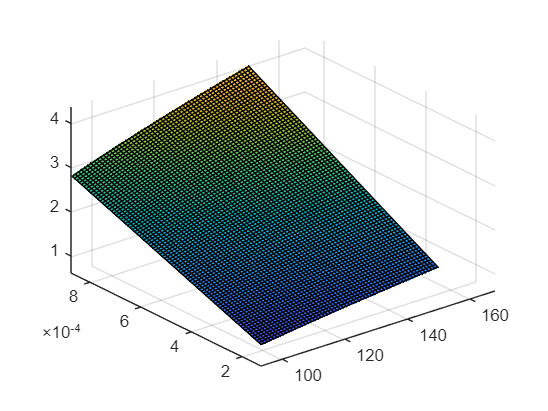

%syms If;

Mr = 2.333;
Ir = 0.01174;
h = 0.05;
g = 9.806;


N = 100;
wf = linspace(50,150,N);
If = linspace(0.0001,0.001,N);
t = sqrt(2*h/g);


wr = sqrt(If/Ir).*wf;

theta = wr.*t;

for i = 1:N
    for j = 1:N
        theta(j,i) = sqrt(If(i)/Ir)*wf(j)*t;
    end
end

surf(wf,If,theta)

xlabel('Vitesse angulaire (rad/s)')
ylabel('Inertie (kg*m^2)')
zlabel('angle (rad)')
